# Denoise Speech Using Deep Learning Networks

This example shows how to denoise speech signals using deep learning networks. The example compares two types of networks applied to the same task: fully connected, and convolutional.

## Introduction

The aim of speech denoising is to remove noise from speech signals while enhancing the quality and intelligibility of speech. This example showcases the removal of washing machine noise from speech signals using deep learning networks. The example compares two types of networks applied to the same task: fully connected, and convolutional.

## Problem Summary

Consider the following speech signal sampled at 8 kHz.

Add washing machine noise to the speech signal. Set the noise power such that the signal-to-noise ratio (SNR) is zero dB. 

clear

[noise,inputfs] = audioread("WashingMachine_48k_120secs.wav");
src = dsp.SampleRateConverter('InputSampleRate',inputfs,'OutputSampleRate',16000,'Bandwidth',15800);
noise = src(noise);

## Examine the Dataset

dataFolder = "../../supportfiles/audio";
datasetTrain = fullfile(dataFolder,"LibriSpeech","train-clean-100");
adsTrain = audioDatastore(datasetTrain,IncludeSubfolders=true);
samples=50;
adsTrain = subset(adsTrain,1:samples);

Use `read` to get the contents of the first file in the datastore.

[audio,adsTrainInfo] = read(adsTrain);

Listen to the speech signal.

%sound(audio,adsTrainInfo.SampleRate)

## STFT Targets and Predictors

This section illustrates how to generate the target and predictor signals from one training file.

First, define system parameters:

windowLength = 256;
win = hamming(windowLength,"periodic");
overlap = round(0.75*windowLength);
fftLength = windowLength;
inputFs = adsTrainInfo.SampleRate;
fs = adsTrainInfo.SampleRate;
numFeatures = fftLength/2;
numSegments = 8;

Use `read` to get the contents of an audio file from the datastore.

audio = read(adsTrain);

Create a random noise segment from the washing machine noise vector.

randind = randi(numel(noise) - numel(audio),[1 1]);
noiseSegment = noise(randind:randind + numel(audio) - 1);

Add noise to the speech signal such that the SNR is 0 dB.

noisePower = sum(noiseSegment.^2);
cleanPower = sum(audio.^2);
noiseSegment = noiseSegment.*sqrt(cleanPower/noisePower);
noisyAudio = audio + noiseSegment;

Use [stft](docid:signal_ref#mw_f6bebd3d-2957-47ad-94bc-6982eed99a32) to generate magnitude STFT vectors from the original and noisy audio signals.

cleanSTFT = stft(audio,Window=win,OverlapLength=overlap,fftLength=fftLength);
cleanSTFT = abs(cleanSTFT(numFeatures+1:end,:));
noisySTFT = stft(noisyAudio,Window=win,OverlapLength=overlap,fftLength=fftLength);
noisySTFT = abs(noisySTFT(numFeatures+1:end,:));


noisySTFT = [noisySTFT(:,1:numSegments - 1),noisySTFT];
stftSegments = zeros(numFeatures,numSegments,size(noisySTFT,2) - numSegments + 1);
for index = 1:size(noisySTFT,2) - numSegments + 1
    stftSegments(:,:,index) = noisySTFT(:,index:index + numSegments - 1); 
end

Set the targets and predictors. The last dimension of both variables corresponds to the number of distinct predictor/target pairs generated by the audio file. Each predictor is 129-by-8, and each target is 129-by-1.

targets = cleanSTFT;
size(targets)

ans =          128        3483


predictors = noisySTFT;
size(predictors)

ans =          128        3490


## Extract Features Using Tall Arrays

To speed up processing, extract feature sequences from the speech segments of all audio files in the datastore using tall arrays. Unlike in-memory arrays, tall arrays typically remain unevaluated until you call the `gather` function. This deferred evaluation enables you to work quickly with large data sets. When you eventually request output using `gather`, MATLAB combines the queued calculations where possible and takes the minimum number of passes through the data. If you have Parallel Computing Toolbox™, you can use tall arrays in your local MATLAB session, or on a local parallel pool. You can also run tall array calculations on a cluster if you have MATLAB® Parallel Server™ installed.

First, convert the datastore to a tall array.

reset(adsTrain)
T = tall(adsTrain)

Starting parallel pool (parpool) using the 'Processes' profile ...
Connected to the parallel pool (number of workers: 8).

T =

  M×1 tall cell array

    {225360×1 double}
    {255120×1 double}
    {223120×1 double}
    {235360×1 double}
    {200240×1 double}
    {242800×1 double}
    {153280×1 double}
    {240560×1 double}
        :        :
        :        :



The display indicates that the number of rows (corresponding to the number of files in the datastore), M, is not yet known. M is a placeholder until the calculation completes.

Extract the target and predictor magnitude STFT from the tall table. This action creates new tall array variables to use in subsequent calculations. The function `HelperGenerateSpeechDenoisingFeatures` performs the steps already highlighted in the STFT Targets and Predictors section. The `cellfun` command applies `HelperGenerateSpeechDenoisingFeatures` to the contents of each audio file in the datastore.

[targets,predictors] = cellfun(@(x)HelperGenerateSpeechDenoisingFeatures2(x,noise),T,UniformOutput=false);

Use `gather` to evaluate the targets and predictors.

[targets,predictors] = gather(targets,predictors);

Evaluating tall expression using the Parallel Pool 'Processes':
- Pass 1 of 1: Completed in 25 sec
Evaluation completed in 45 sec


It is gll features tood practice to normalize ao zero mean and unity standard deviation.

Compute the mean and standard deviation of the predictors and targets, respectively, and use them to normalize the data.

predictors = cat(3,predictors{:});
noisyMean = mean(predictors(:));
noisyStd = std(predictors(:));
predictors(:) = (predictors(:) - noisyMean)/noisyStd;

targets = cat(2,targets{:});
cleanMean = mean(targets(:));
cleanStd = std(targets(:));
targets(:) = (targets(:) - cleanMean)/cleanStd;

Reshape predictors and targets to the dimensions expected by the deep learning networks.

predictors = reshape(predictors,size(predictors,1),size(predictors,2),1,size(predictors,3));
targets = reshape(targets,1,1,size(targets,1),size(targets,2));

You will use 1% of the data for validation during training. Validation is useful to detect scenarios where the network is overfitting the training data.

Randomly split the data into training and validation sets.

inds = randperm(size(predictors,4));
L = round(0.99*size(predictors,4));

trainPredictors = predictors(:,:,:,inds(1:L));
trainTargets = targets(:,:,:,inds(1:L));

validatePredictors = predictors(:,:,:,inds(L+1:end));
validateTargets = targets(:,:,:,inds(L+1:end));

## Speech Denoising with Fully Connected Layers

You first consider a denoising network comprised of fully connected layers. Each neuron in a fully connected layer is connected to all activations from the previous layer. A fully connected layer multiplies the input by a weight matrix and then adds a bias vector. The dimensions of the weight matrix and bias vector are determined by the number of neurons in the layer and the number of activations from the previous layer.

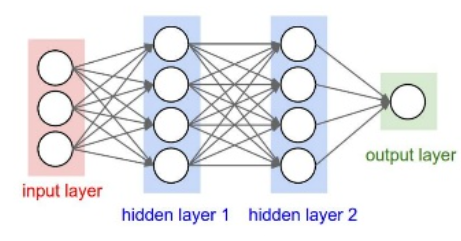

Define the layers of the network. Specify the input size to be images of size `NumFeatures`-by-`NumSegments` (129-by-8 in this example). Define two hidden fully connected layers, each with 1024 neurons. Since purely linear systems, follow each hidden fully connected layer with a Rectified Linear Unit (ReLU) layer. The batch normalization layers normalize the means and standard deviations of the outputs. Add a fully connected layer with 129 neurons, followed by a regression layer.

lgraph = layerGraph();
tempLayers = [
    imageInputLayer([512 numSegments 1],"Name","imageinput")
    convolution2dLayer([9 1],64,"Name","conv","Padding","same",Stride=[1 100])
    convolution2dLayer([3 3],64,"Name","DialedConv","Padding","same")
    reluLayer("Name","relu")
    batchNormalizationLayer("Name","batchnorm")
    convolution2dLayer([1 1],64,"Name","conv_1","Padding","same")];
lgraph = addLayers(lgraph,tempLayers);

tempLayers = [
    maxPooling2dLayer([2 2],"Name","maxpool","Padding","same","Stride",[2 2])
    convolution2dLayer([1 1],128,"Name","conv_2","Padding","same")
    convolution2dLayer([3 3],128,"Name","DialedConv_1","DilationFactor",[2 2],"Padding","same")
    reluLayer("Name","relu_1")
    batchNormalizationLayer("Name","batchnorm_1")
    convolution2dLayer([1 1],128,"Name","conv_3","Padding","same")];
lgraph = addLayers(lgraph,tempLayers);

tempLayers = [
    maxPooling2dLayer([2 2],"Name","maxpool_2","Padding","same","Stride",[2 2])
    convolution2dLayer([1 1],256,"Name","conv_10","Padding","same")
    convolution2dLayer([3 3],256,"Name","DialedConv_2","DilationFactor",[3 3],"Padding","same")
    reluLayer("Name","relu_8")
    batchNormalizationLayer("Name","batchnorm_8")
    convolution2dLayer([1 1],256,"Name","conv_11","Padding","same")];
lgraph = addLayers(lgraph,tempLayers);

tempLayers = [
    maxPooling2dLayer([2 2],"Name","maxpool_3","Padding","same","Stride",[2 2])
    convolution2dLayer([1 1],512,"Name","conv_14","Padding","same")
    convolution2dLayer([3 3],512,"Name","DialedConv_3","DilationFactor",[4 4],"Padding","same")
    reluLayer("Name","relu_11")
    batchNormalizationLayer("Name","batchnorm_11")
    convolution2dLayer([1 1],512,"Name","conv_15","Padding","same")];
lgraph = addLayers(lgraph,tempLayers);

tempLayers = [
    maxPooling2dLayer([2 2],"Name","maxpool_4","Padding","same","Stride",[2 2])
    convolution2dLayer([1 1],1024,"Name","conv_20","Padding","same")
    convolution2dLayer([3 3],1024,"Name","DialedConv_4","DilationFactor",[5 5],"Padding","same")
    reluLayer("Name","relu_16")
    batchNormalizationLayer("Name","batchnorm_16")
    convolution2dLayer([1 1],1024,"Name","conv_21","Padding","same")];
lgraph = addLayers(lgraph,tempLayers);

tempLayers = [
    maxPooling2dLayer([2 2],"Name","maxpool_5","Padding","same","Stride",[2 2])
    convolution2dLayer([1 1],1024,"Name","conv_28","Padding","same")
    convolution2dLayer([3 3],1024,"Name","DialedConv_5","DilationFactor",[6 6],"Padding","same")
    reluLayer("Name","relu_23")
    batchNormalizationLayer("Name","batchnorm_23")
    convolution2dLayer([1 1],1024,"Name","conv_29","Padding","same")];
lgraph = addLayers(lgraph,tempLayers);

tempLayers = [
    maxPooling2dLayer([2 2],"Name","maxpool_6","Padding","same","Stride",[2 2])
    convolution2dLayer([1 1],1024,"Name","conv_30","Padding","same")
    convolution2dLayer([3 3],1024,"Name","DialedConv_6","DilationFactor",[7 7],"Padding","same")
    reluLayer("Name","relu_24")
    batchNormalizationLayer("Name","batchnorm_24")
    convolution2dLayer([1 1],1024,"Name","conv_31","Padding","same")];
lgraph = addLayers(lgraph,tempLayers);

tempLayers = [
    maxPooling2dLayer([2 2],"Name","maxpool_7","Padding","same","Stride",[2 2])
    convolution2dLayer([1 1],1024,"Name","conv_32","Padding","same")
    convolution2dLayer([3 3],1024,"Name","DialedConv_7","DilationFactor",[8 8],"Padding","same")
    reluLayer("Name","relu_25")
    batchNormalizationLayer("Name","batchnorm_25")
    convolution2dLayer([1 1],1024,"Name","conv_33","Padding","same")];
lgraph = addLayers(lgraph,tempLayers);

tempLayers = [
    maxPooling2dLayer([2 2],"Name","maxpool_1","Padding","same","Stride",[2 2])
    convolution2dLayer([3 3],1024,"Name","conv_4","Padding","same")
    reluLayer("Name","relu_2")
    batchNormalizationLayer("Name","batchnorm_2")
    convolution2dLayer([3 3],1024,"Name","conv_5","Padding","same")
    reluLayer("Name","relu_3")
    batchNormalizationLayer("Name","batchnorm_3")
    transposedConv2dLayer([2 1],1024,"Name","transposed-conv","Cropping","same","Stride",[2 1])
    ];
lgraph = addLayers(lgraph,tempLayers);

tempLayers = [
    depthConcatenationLayer(2,"Name","depthcat_7")
    convolution2dLayer([3 3],1024,"Name","conv_26","Padding","same")
    reluLayer("Name","relu_21")
    batchNormalizationLayer("Name","batchnorm_21")
    convolution2dLayer([3 3],1024,"Name","conv_27","Padding","same")
    reluLayer("Name","relu_22")
    batchNormalizationLayer("Name","batchnorm_22")
    transposedConv2dLayer([2 2],1024,"Name","transposed-conv_1","Cropping","same","Stride",[2 1])];
lgraph = addLayers(lgraph,tempLayers);

tempLayers = [
    depthConcatenationLayer(2,"Name","depthcat_6")
    convolution2dLayer([3 3],1024,"Name","conv_24","Padding","same")
    reluLayer("Name","relu_19")
    batchNormalizationLayer("Name","batchnorm_19")
    convolution2dLayer([3 3],1024,"Name","conv_25","Padding","same")
    reluLayer("Name","relu_20")
    batchNormalizationLayer("Name","batchnorm_20")
    transposedConv2dLayer([2 2],1024,"Name","transposed-conv_2","Cropping","same","Stride",[2 1])];
lgraph = addLayers(lgraph,tempLayers);

tempLayers = [
    depthConcatenationLayer(2,"Name","depthcat_5")
    convolution2dLayer([3 3],1024,"Name","conv_22","Padding","same")
    reluLayer("Name","relu_17")
    batchNormalizationLayer("Name","batchnorm_17")
    convolution2dLayer([3 3],1024,"Name","conv_23","Padding","same")
    reluLayer("Name","relu_18")
    batchNormalizationLayer("Name","batchnorm_18")
    transposedConv2dLayer([2 2],1024,"Name","transposed-conv_3","Cropping","same","Stride",[2 1])];
lgraph = addLayers(lgraph,tempLayers);

tempLayers = [
    depthConcatenationLayer(2,"Name","depthcat_4")
    convolution2dLayer([3 3],1024,"Name","conv_18","Padding","same")
    reluLayer("Name","relu_14")
    batchNormalizationLayer("Name","batchnorm_14")
    convolution2dLayer([3 3],1024,"Name","conv_19","Padding","same")
    reluLayer("Name","relu_15")
    batchNormalizationLayer("Name","batchnorm_15")
    transposedConv2dLayer([2 2],512,"Name","transposed-conv_4","Cropping","same","Stride",[2 1])];
lgraph = addLayers(lgraph,tempLayers);

tempLayers = [
    depthConcatenationLayer(2,"Name","depthcat_3")
    convolution2dLayer([3 3],512,"Name","conv_16","Padding","same")
    reluLayer("Name","relu_12")
    batchNormalizationLayer("Name","batchnorm_12")
    convolution2dLayer([3 3],512,"Name","conv_17","Padding","same")
    reluLayer("Name","relu_13")
    batchNormalizationLayer("Name","batchnorm_13")
    transposedConv2dLayer([2 2],256,"Name","transposed-conv_5","Cropping","same","Stride",[2 1])];
lgraph = addLayers(lgraph,tempLayers);

tempLayers = [
    depthConcatenationLayer(2,"Name","depthcat_2")
    convolution2dLayer([3 3],256,"Name","conv_12","Padding","same")
    reluLayer("Name","relu_9")
    batchNormalizationLayer("Name","batchnorm_9")
    convolution2dLayer([3 3],256,"Name","conv_13","Padding","same")
    reluLayer("Name","relu_10")
    batchNormalizationLayer("Name","batchnorm_10")
    transposedConv2dLayer([2 2],128,"Name","transposed-conv_6","Cropping","same","Stride",[2 1])];
lgraph = addLayers(lgraph,tempLayers);

tempLayers = [
    depthConcatenationLayer(2,"Name","depthcat")
    convolution2dLayer([3 3],128,"Name","conv_6","Padding","same")
    reluLayer("Name","relu_4")
    batchNormalizationLayer("Name","batchnorm_4")
    convolution2dLayer([3 3],128,"Name","conv_7","Padding","same")
    reluLayer("Name","relu_5")
    batchNormalizationLayer("Name","batchnorm_5")
    transposedConv2dLayer([2 2],64,"Name","transposed-conv_7","Cropping","same","Stride",[2 1])];
lgraph = addLayers(lgraph,tempLayers);

tempLayers = [
    depthConcatenationLayer(2,"Name","depthcat_1")
    convolution2dLayer([3 3],64,"Name","conv_8","Padding","same")
    reluLayer("Name","relu_6")
    batchNormalizationLayer("Name","batchnorm_6")
    convolution2dLayer([3 3],64,"Name","conv_9","Padding","same")
    reluLayer("Name","relu_7")
    batchNormalizationLayer("Name","batchnorm_7")
    regressionLayer("Name","regressionoutput")];
lgraph = addLayers(lgraph,tempLayers);

% clean up helper variable
clear tempLayers;

lgraph = connectLayers(lgraph,"conv_1","maxpool");
lgraph = connectLayers(lgraph,"conv_1","depthcat_1/in1");
lgraph = connectLayers(lgraph,"conv_3","maxpool_2");
lgraph = connectLayers(lgraph,"conv_3","depthcat/in1");
lgraph = connectLayers(lgraph,"conv_11","maxpool_3");
lgraph = connectLayers(lgraph,"conv_11","depthcat_2/in1");
lgraph = connectLayers(lgraph,"conv_15","maxpool_4");
lgraph = connectLayers(lgraph,"conv_15","depthcat_3/in1");
lgraph = connectLayers(lgraph,"conv_21","maxpool_5");
lgraph = connectLayers(lgraph,"conv_21","depthcat_4/in1");
lgraph = connectLayers(lgraph,"conv_29","maxpool_6");
lgraph = connectLayers(lgraph,"conv_29","depthcat_5/in1");
lgraph = connectLayers(lgraph,"conv_31","maxpool_7");
lgraph = connectLayers(lgraph,"conv_31","depthcat_6/in1");
lgraph = connectLayers(lgraph,"conv_33","maxpool_1");
lgraph = connectLayers(lgraph,"conv_33","depthcat_7/in1");
lgraph = connectLayers(lgraph,"transposed-conv","depthcat_7/in2");
lgraph = connectLayers(lgraph,"transposed-conv_1","depthcat_6/in2");
lgraph = connectLayers(lgraph,"transposed-conv_2","depthcat_5/in2");
lgraph = connectLayers(lgraph,"transposed-conv_3","depthcat_4/in2");
lgraph = connectLayers(lgraph,"transposed-conv_4","depthcat_3/in2");
lgraph = connectLayers(lgraph,"transposed-conv_5","depthcat_2/in2");
lgraph = connectLayers(lgraph,"transposed-conv_6","depthcat/in2");
lgraph = connectLayers(lgraph,"transposed-conv_7","depthcat_1/in2");


analyzeNetwork(lgraph)

Next, specify the training options for the network. Set `MaxEpochs` to `3` so that the network makes 3 passes through the training data. Set `MiniBatchSize` of `128` so that the network looks at 128 training signals at a time. Specify `Plots` as `"training-progress"` to generate plots that show the training progress as the number of iterations increases. Set `Verbose` to `false` to disable printing the table output that corresponds to the data shown in the plot into the command line window. Specify `Shuffle` as `"every-epoch"` to shuffle the training sequences at the beginning of each epoch. Specify `LearnRateSchedule` to `"piecewise"` to decrease the learning rate by a specified factor (0.9) every time a certain number of epochs (1) has passed. Set `ValidationData` to the validation predictors and targets. Set `ValidationFrequency` such that the validation mean square error is computed once per epoch. This example uses the adaptive moment estimation (Adam) solver.

miniBatchSize = 128;
options = trainingOptions("adam", ...
    MaxEpochs=3, ...
    InitialLearnRate=1e-5,...
    MiniBatchSize=miniBatchSize, ...
    Shuffle="every-epoch", ...
    Plots="training-progress", ...
    Verbose=false, ...
    ValidationFrequency=floor(size(trainPredictors,4)/miniBatchSize), ...
    LearnRateSchedule="piecewise", ...
    LearnRateDropFactor=0.9, ...
    LearnRateDropPeriod=1, ...
    ValidationData={validatePredictors,validateTargets});

Train the network with the specified training options and layer architecture using `trainNetwork`. Because the training set is large, the training process can take several minutes. To download and load a pre-trained network instead of training a network from scratch, set `downloadPretrainedSystem` to `true`.

UnetModel = trainNetwork(trainPredictors,trainTargets,lgraph,options);

Error using trainNetwork
Invalid network.

Caused by:
    Layer 'depthcat_7': Input size mismatch. Size of input to this layer is different from the expected input size.
    Inputs to this layer:
        from layer 'conv_33' (size 1(S) × 1(S) × 1024(C) × 1(B))
        from layer 'transposed-conv' (size 2(S) × 2(S) × 1024(C) × 1(B))

Count the number of weights in the fully connected layers of the network.

numWeights = 0;
for index = 1:numel(denoiseNetFullyConnected.Layers)
    if isa(denoiseNetFullyConnected.Layers(index),"nnet.cnn.layer.FullyConnectedLayer")
        numWeights = numWeights + numel(denoiseNetFullyConnected.Layers(index).Weights);
    end
end
disp("Number of weights = " + numWeights);

## Speech Denoising with Convolutional Layers

Consider a network that uses convolutional layers instead of fully connected layers [3]. A 2-D convolutional layer applies sliding filters to the input. The layer convolves the input by moving the filters along the input vertically and horizontally and computing the dot product of the weights and the input, and then adding a bias term. Convolutional layers typically consist of fewer parameters than fully connected layers.

Define the layers of the fully convolutional network described in [3], comprising 16 convolutional layers. The first 15 convolutional layers are groups of 3 layers, repeated 5 times, with filter widths of 9, 5, and 9, and number of filters of 18, 30 and 8, respectively. The last convolutional layer has a filter width of 129 and 1 filter. In this network, convolutions are performed in only one direction (along the frequency dimension), and the filter width along the time dimension is set to 1 for all layers except the first one. Similar to the fully connected network, convolutional layers are followed by ReLu and batch normalization layers.

layers = [imageInputLayer([numFeatures,numSegments])
          convolution2dLayer([9 8],18,Stride=[1 100],Padding="same")
          batchNormalizationLayer
          reluLayer
          
          repmat( ...
          [convolution2dLayer([5 1],30,Stride=[1 100],Padding="same")
          batchNormalizationLayer
          reluLayer
          convolution2dLayer([9 1],8,Stride=[1 100],Padding="same")
          batchNormalizationLayer
          reluLayer
          convolution2dLayer([9 1],18,Stride=[1 100],Padding="same")
          batchNormalizationLayer
          reluLayer],4,1)
          
          convolution2dLayer([5 1],30,Stride=[1 100],Padding="same")
          batchNormalizationLayer
          reluLayer
          convolution2dLayer([9 1],8,Stride=[1 100],Padding="same")
          batchNormalizationLayer
          reluLayer
          
          convolution2dLayer([129 1],1,Stride=[1 100],Padding="same")
          
          regressionLayer
          ];

The training options are identical to the options for the fully connected network, except that the dimensions of the validation target signals are permuted to be consistent with the dimensions expected by the regression layer.

options = trainingOptions("adam", ...
    MaxEpochs=3, ...
    InitialLearnRate=1e-5, ...
    MiniBatchSize=miniBatchSize, ...
    Shuffle="every-epoch", ...
    Plots="training-progress", ...
    Verbose=false, ...
    ValidationFrequency=floor(size(trainPredictors,4)/miniBatchSize), ...
    LearnRateSchedule="piecewise", ...
    LearnRateDropFactor=0.9, ...
    LearnRateDropPeriod=1, ...
    ValidationData={validatePredictors,permute(validateTargets,[3 1 2 4])});

Train the network with the specified training options and layer architecture using `trainNetwork`. Because the training set is large, the training process can take several minutes. To download and load a pre-trained network instead of training a network from scratch, set `downloadPretrainedSystem` to `true`.

denoiseNetFullyConvolutional = trainNetwork(trainPredictors,permute(trainTargets,[3 1 2 4]),layers,options);


Count the number of weights in the fully connected layers of the network.

numWeights = 0;
for index = 1:numel(denoiseNetFullyConvolutional.Layers)
    if isa(denoiseNetFullyConvolutional.Layers(index),"nnet.cnn.layer.Convolution2DLayer")
        numWeights = numWeights + numel(denoiseNetFullyConvolutional.Layers(index).Weights);
    end
end
disp("Number of weights in convolutional layers = " + numWeights);

## Test the Denoising Networks

Read in the test data set.

samples=500;
adsShuffle = shuffle(audioDatastore(datasetTrain,IncludeSubfolders=true));
adsTest = subset(adsShuffle,1:samples);

Read the contents of a file from the datastore.

[cleanAudio,adsTestInfo] = read(adsTest);

In this testing stage, you corrupt speech with washing machine noise not used in the training stage.

[noise,inputfs] = audioread("WashingMachine-16-8-mono-200secs.mp3");
src = dsp.SampleRateConverter('InputSampleRate',inputfs,'OutputSampleRate',16000,'Bandwidth',15800);
noise = src(noise);
%sound(noise,16000);

Create a random noise segment from the washing machine noise vector.

randind = randi(numel(noise) - numel(cleanAudio), [1 1]);
noiseSegment = noise(randind:randind + numel(cleanAudio) - 1);

Add noise to the speech signal such that the SNR is 0 dB.

noisePower = sum(noiseSegment.^2);
cleanPower = sum(cleanAudio.^2);
noiseSegment = noiseSegment;
noisyAudio = cleanAudio + noiseSegment;

Use `stft` to generate magnitude STFT vectors from the noisy audio signals.

noisySTFT = stft(noisyAudio,Window=win,OverlapLength=overlap,fftLength=fftLength);
noisyPhase = angle(noisySTFT(numFeatures-1:end,:));
noisySTFT = abs(noisySTFT(numFeatures-1:end,:));

Generate the 8-segment training predictor signals from the noisy STFT. The overlap between consecutive predictors is 7 segments.

noisySTFT = [noisySTFT(:,1:numSegments-1) noisySTFT];
predictors = zeros(numFeatures,numSegments,size(noisySTFT,2) - numSegments + 1);
for index = 1:(size(noisySTFT,2) - numSegments + 1)
    predictors(:,:,index) = noisySTFT(:,index:index + numSegments - 1); 
end

Normalize the predictors by the mean and standard deviation computed in the training stage.

predictors(:) = (predictors(:) - noisyMean)/noisyStd;

Compute the denoised magnitude STFT by using `predict` with the two trained networks.

predictors = reshape(predictors,[numFeatures,numSegments,1,size(predictors,3)]);
STFTFullyConnected = predict(denoiseNetFullyConnected,predictors);
STFTFullyConvolutional = predict(denoiseNetFullyConvolutional,predictors);

Scale the outputs by the mean and standard deviation used in the training stage.

STFTFullyConnected(:) = cleanStd*STFTFullyConnected(:) + cleanMean;
STFTFullyConvolutional(:) = cleanStd*STFTFullyConvolutional(:) + cleanMean;

Convert the one-sided STFT to a centered STFT.

STFTFullyConnected = (STFTFullyConnected.').*exp(1j*noisyPhase);
STFTFullyConnected = [conj(STFTFullyConnected(end-1:-1:2,:));STFTFullyConnected];
STFTFullyConvolutional = squeeze(STFTFullyConvolutional).*exp(1j*noisyPhase);
STFTFullyConvolutional = [conj(STFTFullyConvolutional(end-1:-1:2,:));STFTFullyConvolutional];

Compute the denoised speech signals. `istft` performs the inverse STFT. Use the phase of the noisy STFT vectors to reconstruct the time-domain signal.

denoisedAudioFullyConnected = istft(STFTFullyConnected,Window=win,OverlapLength=overlap,fftLength=fftLength,ConjugateSymmetric=true);                       
denoisedAudioFullyConvolutional = istft(STFTFullyConvolutional,Window=win,OverlapLength=overlap,fftLength=fftLength,ConjugateSymmetric=true);

Plot the clean, noisy and denoised audio signals.

t = (1/fs)*(0:numel(denoisedAudioFullyConnected)-1);

figure(3)
tiledlayout(4,1)

nexttile
plot(t,cleanAudio(1:numel(denoisedAudioFullyConnected)))
title("Clean Speech")
grid on

nexttile
plot(t,noisyAudio(1:numel(denoisedAudioFullyConnected)))
title("Noisy Speech")
grid on

nexttile
plot(t,denoisedAudioFullyConnected)
title("Denoised Speech (Fully Connected Layers)")
grid on

nexttile
plot(t,denoisedAudioFullyConvolutional)
title("Denoised Speech (Convolutional Layers)")
grid on
xlabel("Time (s)")

Plot the clean, noisy, and denoised spectrograms.

h = figure(4);
tiledlayout(4,1)

nexttile
spectrogram(cleanAudio,win,overlap,fftLength,fs);
title("Clean Speech")
grid on

nexttile
spectrogram(noisyAudio,win,overlap,fftLength,fs);
title("Noisy Speech")
grid on

nexttile
spectrogram(denoisedAudioFullyConnected,win,overlap,fftLength,fs);
title("Denoised Speech (Fully Connected Layers)")
grid on

nexttile
spectrogram(denoisedAudioFullyConvolutional,win,overlap,fftLength,fs);
title("Denoised Speech (Convolutional Layers)")
grid on

p = get(h,"Position");
set(h,"Position",[p(1) 65 p(3) 800]);

Listen to the noisy speech.

sound(noisyAudio,fs)

Listen to the denoised speech from the network with fully connected layers.

sound(denoisedAudioFullyConnected,fs)

Listen to the denoised speech from the network with convolutional layers.

sound(denoisedAudioFullyConvolutional,fs)

Listen to clean speech.

sound(cleanAudio,fs)

You can test more files from the datastore by calling `testDenoisingNets`. The function produces the time-domain and frequency-domain plots highlighted above, and also returns the clean, noisy, and denoised audio signals.

[cleanAudio,noisyAudio,denoisedAudioFullyConnected,denoisedAudioFullyConvolutional] = testDenoisingNets(adsTest,denoiseNetFullyConnected,denoiseNetFullyConvolutional,noisyMean,noisyStd,cleanMean,cleanStd);

function [targets,predictors] = HelperGenerateSpeechDenoisingFeatures2(audio,noise)
% HelperGenerateSpeechDenoisingFeatures: Get target and predictor STFT
% signals for speech denoising.
% audio: Input audio signal
% noise: Input noise signal
% src:   Sample rate converter

% Copyright 2018 The MathWorks, Inc.


WindowLength = 256*4;
win          = hamming(WindowLength,'periodic');
Overlap      = round(0.75 * WindowLength);
FFTLength    = WindowLength;
NumFeatures  = FFTLength/2 + 1;
NumSegments  = 8;

randind      = randi(numel(noise) - numel(audio) , [1 1]);
noiseSegment = noise(randind : randind + numel(audio) - 1);

noisePower   = sum(noiseSegment.^2);
cleanPower   = sum(audio.^2);
noiseSegment = noiseSegment .* sqrt(cleanPower/noisePower);
noisyAudio   = audio + noiseSegment;

cleanSTFT = stft(audio, 'Window',win, 'OverlapLength', Overlap, 'FFTLength',FFTLength);
cleanSTFT = abs(cleanSTFT(NumFeatures-1:end,:));
noisySTFT = stft(noisyAudio, 'Window',win, 'OverlapLength', Overlap, 'FFTLength',FFTLength);
noisySTFT = abs(noisySTFT(NumFeatures-1:end,:));

noisySTFTAugmented = [noisySTFT(:,1:NumSegments-1) noisySTFT];
 
STFTSegments = zeros(NumFeatures, NumSegments , size(noisySTFTAugmented,2) - NumSegments + 1);
for index = 1 : size(noisySTFTAugmented,2) - NumSegments + 1
    STFTSegments(:,:,index) = noisySTFTAugmented(:,index:index+NumSegments-1);
end

targets    = cleanSTFT;
predictors = STFTSegments;

end